Consider the confound of scanner model.

scanner: similarity of scanner model between sites

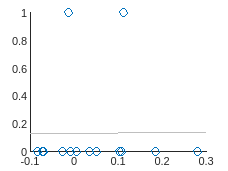

BD


                     scanner 
                     ________

    spearman corr    0.090784
    p                 0.36118



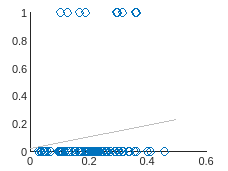

SCZ


                     scanner
                     _______

    spearman corr    0.11236
    p                0.18094



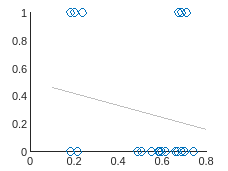

AD


                      scanner 
                     _________

    spearman corr    -0.034816
    p                  0.49942



% Clear all variables and close all figures
clear all % Remove all variables from the workspace to ensure a clean start
close all % Close all open figure windows

% Initialize parameters
iCOMBAT = 1; % Flag to determine if COMBAT harmonization is applied (1 = applied, 0 = not applied)
smoothKernel = 6; % Smoothing kernel size for preprocessing
iter = 5000; % Number of iterations for permutation testing
type = 'spearman'; % Type of correlation to compute (Spearman rank correlation)
diagnosisString = {'BD', 'SCA', 'SCZ', 'ASD', 'MDD', 'AD'}; % List of diagnoses to analyze

nDiag = length(diagnosisString); % Calculate the total number of diagnoses

% Set the directory path based on whether COMBAT harmonization is applied
if iCOMBAT == 1
    address = ['derivatives/s', num2str(smoothKernel), 'COMBAT/']; % Path for COMBAT harmonized data
else
    address = ['derivatives/s', num2str(smoothKernel), '/']; % Path for non-COMBAT harmonized data
end

% Load metadata about scanner model and site information
metadata = readtable('/projects/kg98/trangc/VBM/data/scanner_site_detailed.csv', 'VariableNamingRule', 'preserve');

% Load precomputed correlation matrices and site lists
load(['output/corr_tmap_combat', num2str(iCOMBAT), '_smooth', num2str(smoothKernel), '.mat'], ...
     'cor1', 'cor2', 'siteList');

% Loop through each diagnosis
for iDiag = 1:nDiag
    
    % Compute variance related to scanner model similarity between sites
    [varTable{iDiag}, nSite{iDiag}] = cor_var_scannermodel(metadata, ...
        diagnosisString(iDiag), cor1{iDiag}, cor2{iDiag},siteList{iDiag}, iter, type);
    
    % Display results if the variance table is not empty
    if size(varTable{iDiag}, 1) ~= 0
        disp(char(diagnosisString(iDiag))); % Display diagnosis name
        disp(varTable{iDiag}); % Display variance table
        disp(' '); % Add spacing
        disp(' ');
    end
end


% Suppress specific warnings and save the results
warning('off', 'last');

Error using warning
The last warning issued had an empty warning identifier, or no warnings have yet been issued.

save('output/confound_scannerModel.mat', 'varTable', 'nSite');
